# Genetic Algorithm

Michael Kmak

    - from code by Dr. David Mueller

Computational Intelligence

### Problem Statement:

Use a genetic algorithm to find the global optimum of the following objective function:


$$f(x,y)=\exp\left( \frac{-\left[ (x-3)^2+(y-3)^2\right]}{5} \right) +
\exp\left( \frac{-\left[ x^2+(y+3)^2\right]}{5} \right) + 
0.2\left[ \cos\left(\frac{x\pi}{2}\right) + \cos\left(\frac{y\pi}{2}\right)\right] +
0.5$$


objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;

Mathematically we know this function has a maximum height of 1.6903 in the range of -5 to 5 for x and y.

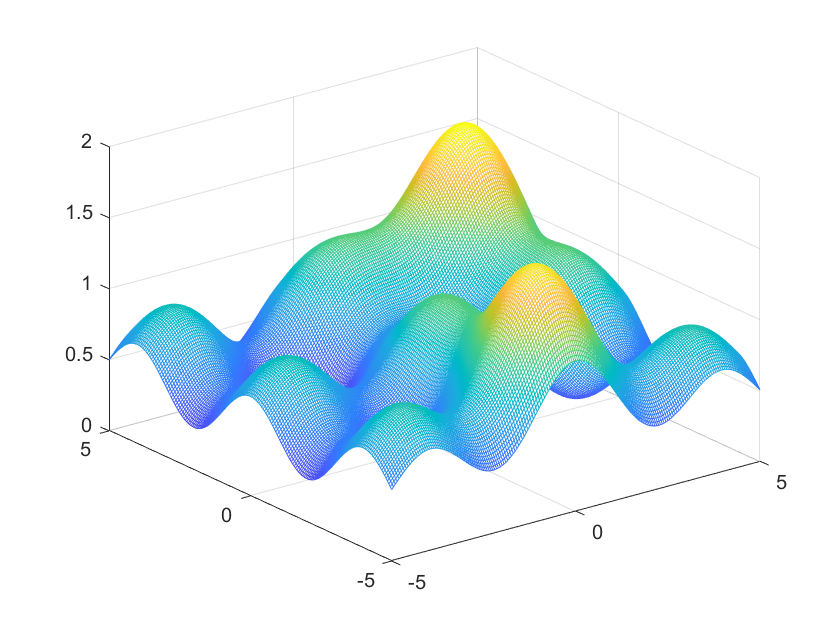

[x,y]=meshgrid(-5:0.05:5);
mesh(x,y,objf(x,y));

### Methods:

- Representation: Binary

- Selection: Proportional (Roulette Wheel) Selection

- Mating/Variation: Single Point Binary Crossover, Uniform Crossover

### Initialize Parameters

For a genetic algorithm, the important parameters are population size, number of generations to execute, fraction of population seleected for mating, the data representation, and the range of data. Also included is the number of trials to run.

clearvars
objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;
% ***** User Changable Variables ***** %
trials = 200;           %how many trials to run
pop = 40;               %population size
gen = 200;              %number of generations
pcntsel = 0.5;          %fraction of candidated selected for next generation

precision = 8;          %precision of real number represenation (ex. 8 -> 8-bit represenation)
range = [-5 5; -5 5];   %bounds for input variables
uniform = 1;            %crossover algorithm


% ***** Calculations ***** %
mu = round(pcntsel*pop);    %number of parents selected
lambda = pop - mu;          %number of new candidates in each generation (children)

best = zeros(trials, gen, 2); % tracking the best candidate in each trial, per generation

### Generate Initial Population

Generally, the initial population is generated randomly within specified ranges. 

% candidate.binx = rand(pop,precision)>0.5;   %generate binary representation
% candidate.biny = rand(pop,precision)>0.5;

### Genetic Algorithm

    for t = 1:trials
        % initialize the new trial
        candidate.binx = rand(pop,precision)>0.5;   %generate binary representation
        candidate.biny = rand(pop,precision)>0.5;
        
        for i = 1:gen
            
            % ********* Convert Representation ****** %
            candidate.x = (range(1,1)-range(1,2))*(bi2de(candidate.binx)/(2^precision-1))+range(1,2);
            candidate.y = (range(2,1)-range(2,2))*(bi2de(candidate.biny)/(2^precision-1))+range(2,2);
            % *************************************** %
            
            % ********* Get Fitness ***************** %
            candidate.fit = objf(candidate.x,candidate.y);
            % record best of the generation
            [~,bi] = max(candidate.fit);
            best(t,i,uniform+1) = candidate.fit(bi);
            % *************************************** %
            
            % ********* Selection ******************* %
            % Linear (Roulette Wheel) Selection
            fitsum = sum(candidate.fit);
            candidate.p = candidate.fit./fitsum;
            % *************************************** %
            
            % ********* Select Parents  ************* %
            parents = zeros(mu,1);
            % discreteinvrnd(p,m,n) generates m by n table of random numbers
            % according to PMF p.
            p = discreteinvrnd(candidate.p);
            for k = 1:mu
                while ismember(p, parents)
                    p = discreteinvrnd(candidate.p);
                end
                parents(k) = p;
            end
            children = setdiff(1:40, parents);
            % *************************************** %
            
            % ********* Create Offspring ************ %
            if ~uniform
                % 1-point
                for k = 1:2:lambda
                    pt = randi(precision-1); % random point to split chromosomes
                    % first child
                    candidate.binx(children(k),:) = horzcat(...
                        candidate.binx(parents(k),1:pt), ...
                        candidate.binx(parents(k+1),pt+1:precision));
                    candidate.biny(children(k),:) = horzcat(...
                        candidate.biny(parents(k),1:pt), ...
                        candidate.biny(parents(k+1),pt+1:precision));
                    % second child (inverse)
                    candidate.binx(children(k+1),:) = horzcat(...
                        candidate.binx(parents(k+1),1:pt), ...
                        candidate.binx(parents(k),pt+1:precision));
                    candidate.biny(children(k+1),:) = horzcat(...
                        candidate.biny(parents(k+1),1:pt), ...
                        candidate.biny(parents(k),pt+1:precision));
                end
            else
                % uniform crossover
                % generates a random bitmap in which each bit is uniformly random
                % and muxes the parents according to it.
                map = rand(lambda,precision)>0.5;
                for k = 1:2:lambda
                    % first child
                    candidate.binx(children(k),:) = mux(...
                        candidate.binx(parents(k),:)...
                        , candidate.binx(parents(k+1),:), map(k,:));
                    candidate.biny(children(k),:) = mux(...
                        candidate.biny(parents(k),:)...
                        , candidate.biny(parents(k+1),:), map(k,:));
                    % second child (inverse)
                    candidate.binx(children(k+1),:) = mux(...
                        candidate.binx(parents(k+1),:)...
                        , candidate.binx(parents(k),:), map(k,:));
                    candidate.biny(children(k+1),:) = mux(...
                        candidate.biny(parents(k+1),:)...
                        , candidate.biny(parents(k),:), map(k,:));
                end
            end
            % *************************************** %
        end
    end

### Results and Conclusions

The algorithm performs reasonably well. It will occasionally converge prematurely, but trends upwards overall. The average solution is sub-optimal. Both of these isues could be solved realitvely simply. Random diversity would help avoid early convergence, such as having 5% of the next generation be generated randomly rather than via crossover. To avoid sub-optimal solutions, keeping the best few candidates would help. Again, a chunk of 5% would probably work well here.

The graphs below illustrate the best candidate with respect to each generation. To differentiate the many trials, the line color is set on a gradient respective to the trial number, from green to yellow to red. Though extremely busy, these graphs illustrate a general trend. The first 25-50 generations are extremely noisy, as the algorithm finds its footing. Unfortunately, it trends downwards somewhere during this process, and the best solutions reach a mean of about 1.56 for the two crossover methods. Many trials display a lack of variety past the initial period of high noise. If the fit were better, this would be a good thing. However, converging at a sub-optimal value seems to show a lack of diversity and the loss of the better-performing candidates. This loss might be caused by the random selection of parents. The best-fit candidates are more likely to survive the initial selection, but then must compete at a uniform probability with lesser candidates to actually pass on their genes. Pairing the parents in a less random fashion would help assure that these genes are carried on. The random selection also lacks a check to assure that parents aren't having children with themselves, which contributes to premature convergence. These could be easily fixed, but I didn't catch the errors until just before the due date as I was helping a classmate with their code, so I don't quite have the time to do so.

#### 1-Point Crossover:

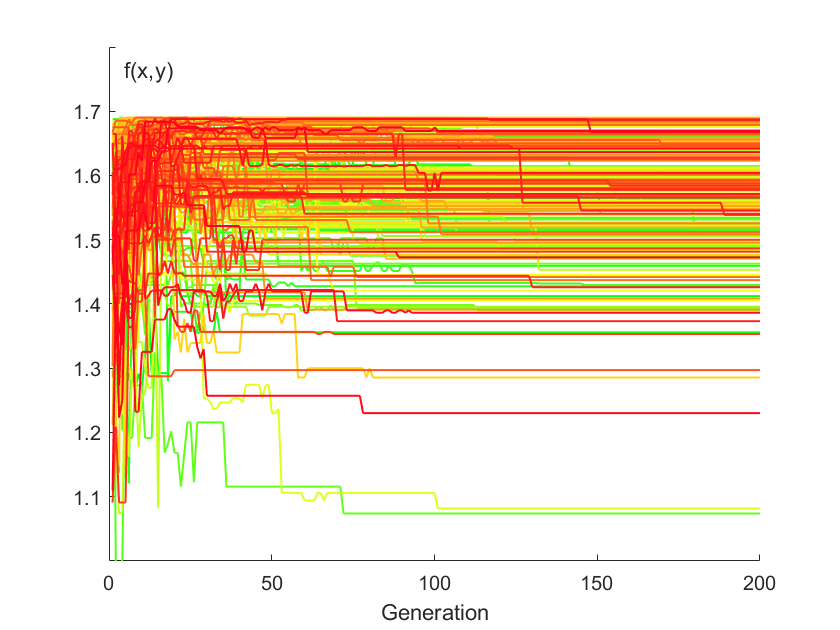

plot_best(best(:,:,1)); % 1-point

#### Uniform Crossover:

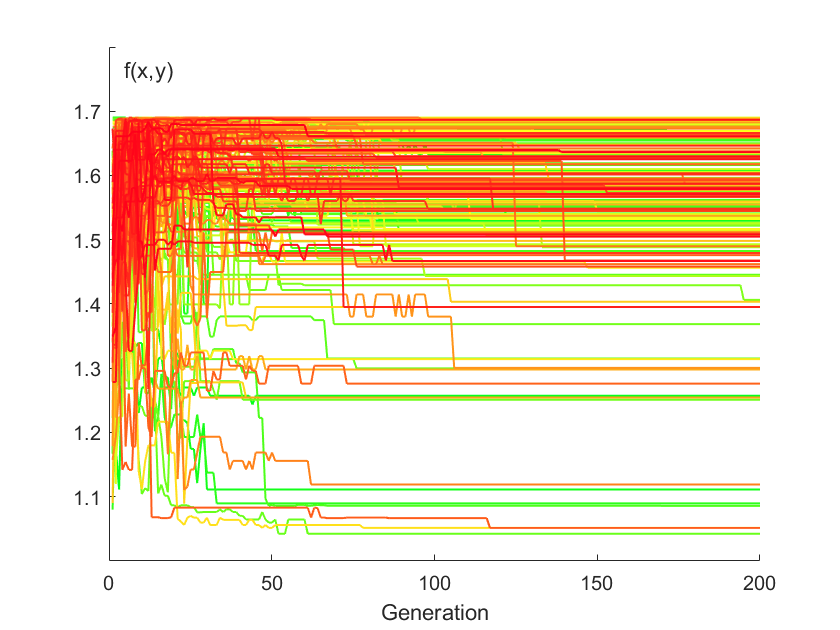

plot_best(best(:,:,2)); % uniform

#### Average of Bests

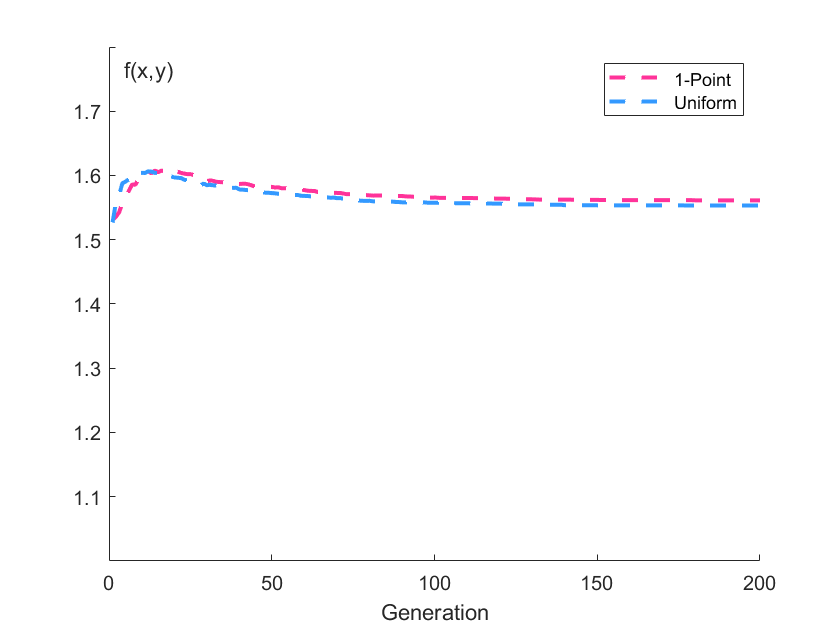

plot_bavg(best);

### Helper Functions

Logical muxer:

function Y = mux(A, B, S)
    Y = (~S & A) | (S & B);
end

Plot the recorded best candidates:

function plot_best(best)
    figure();
    hold on;
    axis([-0.1 width(best) 1 1.8]);
    xlabel('Generation');
    ylabel('f(x,y)');
    ax = gca;
    ax.XAxisLocation='origin';
    ax.YAxisLocation='origin';
    figy = 1:width(best);
    tmax = height(best);
    for t = 1:tmax
        plot(figy, best(t,:), 'Color',[min(t/(0.5*tmax),1) min((tmax-t)/(0.5*tmax),1) .1], 'LineStyle', '-','LineWidth',1);
    end
end

Plot the average of bests for each generation

function plot_bavg(best)
    figure();
    hold on;
    axis([-0.1 width(best) 1 1.8]);
    xlabel('Generation');
    ylabel('f(x,y)');
    ax = gca;
    ax.XAxisLocation='origin';
    ax.YAxisLocation='origin';
    figy = 1:width(best);
    bavg = zeros(width(best),2);
    for i=1:height(best)
        bavg(i,1) = mean(best(:,i,1));
        bavg(i,2) = mean(best(:,i,2));
    end
    plot(figy, bavg(:,1), 'Color',[1 .2 .6], 'LineStyle', '--','LineWidth',2);
    plot(figy, bavg(:,2), 'Color',[.2 .6 1], 'LineStyle', '--','LineWidth',2);
    legend('1-Point', 'Uniform');
end

Generates m*n random numbers according to PMF p. Adapted from [https://www.mathworks.com/help/stats/generating-random-data.html](https://www.mathworks.com/help/stats/generating-random-data.html)

function X = discreteinvrnd(p)
    u = rand;
    I = find(u < cumsum(p));
    X = min(I);
end